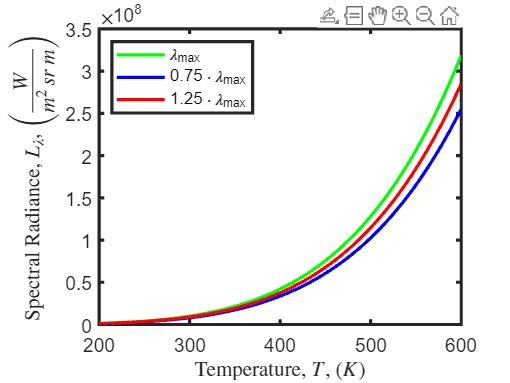

clear; close; clc;

% physical parameters
epsilon = 1; % spectral emisivity (~)

% plotting parameters
n_points_plot = 100; % number of points to plot

T_min = 200; % minimum plotting temperature (K)
T_max = 600; % maximum plotting temperature (K)

lambda_offset = .25; % ratio of lambda to lambda max to plot

% compute values
T = linspace(T_min, T_max, n_points_plot); % produce the Temperatures to plot

lammbda_max = lambda_max_blackbody(T); % Wien's law for waveenth of maximum emmision
L_lambda_max = spectral_radiance_labertian_blackbody(epsilon, T, lammbda_max); % compute maximum spectral radiance

% compute off optimal radiance
lammbda_small = lammbda_max - (lambda_offset * lammbda_max); % offset smaller
lammbda_large = lammbda_max + (lambda_offset * lammbda_max); % offset larger larger
L_lammbda_small = spectral_radiance_labertian_blackbody(epsilon, T, lammbda_small); % compute off optimal spectral radiance
L_lammbda_large = spectral_radiance_labertian_blackbody(epsilon, T, lammbda_large); % compute off optimal spectral radiance

% Plot radiance as a function of temperature
figure;
% maximum radiance
plot(T, L_lambda_max, "-g", "DisplayName","\lambda_{max}", "LineWidth", 2);
% off maximum radiance
hold on;
names = [sprintf("%g\\cdot\\lambda_{max}", 1-lambda_offset), sprintf("%g\\cdot\\lambda_{max}", 1+lambda_offset)];
plot(T, L_lammbda_small, "-b", "DisplayName",names(1), "LineWidth", 2);
plot(T, L_lammbda_large, "-r", "DisplayName",names(2), "LineWidth", 2);


% figure formatting
legend("Location","northwest");
set(gca,"FontSize",12); set(gca,"LineWidth",2);
set(gca,'BoxStyle','back','Layer','bottom');
xlabel("Temperature, $T$, $\left(K\right)$", "Interpreter","latex");
ylabel("Spectral Radiance, $L_{\lambda}$, $\left(\frac{W}{m^2\,sr\,m}\right)$", "Interpreter","latex");